%===================时间序列ARIMA模型的MATLAB代码===================%
% 清空命令窗口内容，清除工作区变量，关闭所有打开的图形窗口
clc;
clear;
close all;

% 输入要进行预测的数据data(列向量)
% 这里生成一个从0到100，步长为0.1的线性序列作为示例数据，然后取其正弦值并转置为列向量
% 实际应用中，此处应替换为真实的时间序列数据
load matlab.mat

data = btc.Value

data = 1.0e+04 *

    0.0622
    0.0610
    0.0611
    0.0609
    0.0610
    0.0609
    0.0607
    0.0612
    0.0610
    0.0609
    0.0599
    0.0597
    0.0594
    0.0604
    0.0602


% 获取输入数据的行数，即数据点的个数
size_data = size(data, 1);

% 输入向后预测的个数P，也就是期望预测未来多少个时间点的数据
P = 100;

% 使用自定义的ARIMA函数对输入数据进行建模预测，得到预测结果data_predict
% ARIMA函数内部实现了ARIMA模型的完整流程，包括平稳性检验、确定模型参数、进行预测等操作
data_predict = ARIMA(data, P);

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                  Value       StandardError    TStatistic     PValue  
                __________    _____________    __________    _________

    Constant      0.085954        0.03041        2.8265      0.0047056
    AR{1}          -0.4907      0.0060613       -80.955              0
    AR{2}         -0.95576      0.0061897       -154.41              0
    MA{1}         -0.56106      0.0057416       -97.718              0
    MA{2}          0.53326      0.0066652        80.007              0
    MA{3}          -0.9722      0.0065145       -149.24              0
    Variance    6.2618e+05           7018        89.225              0



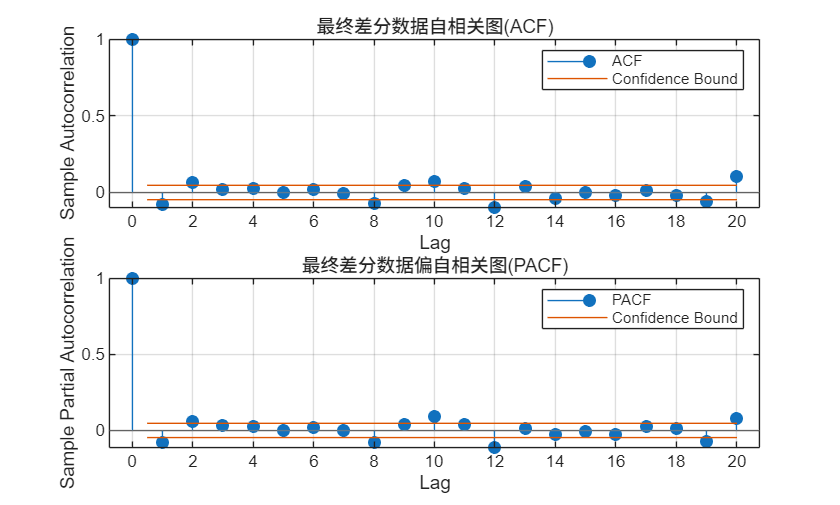


%================================可视化================================%
% 先进性平稳性检验，差分得到平稳的序列
data_diff=data;
d = 0; % 初始化插分次数为0
h = kpsstest(data_diff); % 进行KPSS平稳性检验
% h：平稳性检验的假设检验结果，如果h为1，则拒绝原假设，
% 即数据不是平稳的；如果h为0，则接受原假设，即数据是平稳的。

% 不平稳就进行插分
while h
    data_diff = diff(data_diff); % 对数据进行一阶差分
    h = kpsstest(data_diff); % 重新进行KPSS平稳性检验
    d = d + 1; % 插分次数加1
end

% 画差分后平稳序列的ACF和PACF
figure(1)
subplot(2,1,1)
autocorr(data_diff); % 绘制自相关图（ACF）
title('最终差分数据自相关图(ACF)')
subplot(2,1,2)
parcorr(data_diff); % 绘制偏自相关图（PACF）
title('最终差分数据偏自相关图(PACF)')

%===========================ARIMA的函数部分===========================%
function data_predict = ARIMA(data, P)
    %------------------1.进行平稳性检验,确定插分阶数------------------%
    % 初始化差分次数为0，表示尚未进行差分操作
    d = 0;
    % 使用KPSS检验（一种常用的平稳性检验方法）对输入数据进行平稳性检验
    % h：平稳性检验的假设检验结果，如果h为1，则拒绝原假设，
    % 即数据不是平稳的；如果h为0，则接受原假设，即数据是平稳的。
    h = kpsstest(data);

    % 只要数据不是平稳的（h为1），就进行差分操作，直到数据变为平稳为止
    while h
        % 对数据进行一阶差分，差分可以使非平稳数据变得平稳，常用于时间序列预处理
        data = diff(data);
        % 重新进行KPSS平稳性检验，检查差分后的新数据是否平稳
        h = kpsstest(data);  
        % 每进行一次差分，差分次数加1
        d = d + 1;
    end

    %-----------------2.通过AIC准则来确定最佳p,q值-----------------%
    % 确定p和q的候选值范围，这里简单设定p和q从0到3取值，
    % 在实际应用中可根据数据特点和经验适当调整取值范围
    pValues = 0:3;
    qValues = 0:3;

    % 初始化AIC（赤池信息准则）的最小值为无穷大，
    % 后续在遍历不同模型参数组合时，将不断更新这个最小值以及对应的最佳参数
    minAIC = inf;

    % 遍历不同的p、d、q组合，寻找使得AIC最小的模型参数
    for p = pValues
        for q = qValues
            try
                % 创建ARIMA模型对象，指定自回归阶数p、差分阶数d、移动平均阶数q
                model = arima(p, d, q);

                % 使用输入的数据估计模型的参数，'display', 'off'表示不显示估计过程的详细信息
                % 返回值分别为估计的参数、估计的协方差矩阵以及对数似然值（此处用~忽略前两个返回值）
                [~, ~, logL] = estimate(model, data, 'display', 'off');

                % 根据公式计算AIC值，AIC用于衡量模型的复杂度和拟合优度之间的平衡，
                % 选择AIC最小的模型通常能在避免过拟合的同时获得较好的拟合效果
                aic = -2 * logL + 2 * (p + q + 1);

                % 检查当前模型的AIC是否小于已记录的最小AIC
                if aic < minAIC
                    % 如果是，则更新最小AIC值以及对应的最佳p值和最佳q值
                    minAIC = aic;
                    fit_P = p;  
                    fit_Q = q;  
                end
            catch
                % 如果在创建模型或估计参数过程中出现错误（例如模型不收敛等情况），则跳过当前循环，继续下一组参数尝试
                continue;  
            end
        end
    end

    % 最佳模型参数
    % 将找到的最佳p值赋给变量p，用于后续构建最终的模型
    p = fit_P;  
    % 将找到的最佳q值赋给变量q，用于后续构建最终的模型
    q = fit_Q;  
    % 将找到的最小AIC值赋给变量AIC，可用于记录或后续评估模型的优劣
    AIC = minAIC;  

    %--------------------------3.进行预测--------------------------%
    % 创建最终的ARIMA模型，使用前面确定的最佳p、d、q值
    model = arima(p, d, q);  

    % 使用数据再次估计模型参数，得到最佳拟合的模型对象，这里的bestModel包含了最终确定的模型参数估计结果
    bestModel = estimate(model, data);  

    % 使用最佳模型进行预测，预测未来P个时间点的数据，
    % 'Y0'参数指定了初始条件，这里使用已有的数据作为初始条件，返回预测结果
    data_predict = forecast(bestModel, P, 'Y0', data);  

end

predictMat = data(1:16)'

predictMat =   621.6500  609.6700  610.9200  608.8200  610.3800  609.1100  607.0400  611.5800  610.1900  608.6600  598.8800  597.4200  594.0800  603.8800  601.7400  598.9800


for i = 16:size_data
    predictMat = [predictMat ARIMA(data(1:i),1)];
end

 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant     51.202        39.981         1.2807         0.20031
    AR{1}       0.91371      0.065386         13.974      2.2429e-44
    MA{1}            -1       0.24427        -4.0938      4.2432e-05
    Variance     14.485         9.553         1.5163         0.12944



 
    ARIMA(1,0,1) Model (Gaussian Distribution):
 
                 Value     StandardError    TStatistic      PValue  
                _______    _____________    __________    __________

    Constant      67.61        32.465         2.0825        0.037294
    AR{1}       0.88693      0.053241         16.659      2.6028e-62
    MA{1}            -1       0.25538        -3.9157       9.014e-05
    Variance     15.563        8.1962         1.8988        0.057585



 
    ARIMA(1,0,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant      80.729        42.923          1.8808       0.059997
    AR{1}        0.86551      0.070433          12.288     1.0463e-34
    MA{1}       -0.71407        0.3764         -1.8971        0.05781
    MA{2}       -0.28593       0.33584        -0.85138        0.39456
    Variance      14.416         8.154           1.768       0.077064

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.65425       0.38845         1.6843        0.092133
    AR{1}         -1.706      0.038405        -44.421               0
    AR{2}        -0.8118      0.061734         -13.15      1.7015e-39
    MA{1}         1.0078       0.62152         1.6216

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.58608       0.50831           1.153        0.24891
    AR{1}          -1.63       0.31779          -5.129     2.9128e-07
    AR{2}        -1.2039       0.45004          -2.675      0.0074718
    AR{3}       -0.38809       0.28811          -1.347        0.17798
    MA{1}        0.52653       0.67232         0.78315        0.43354
    MA{2}       -0.52653       0.63325        -0.83147        0.40571
    MA{3}             -1       0.25754         -3.8829     0.00010322
    Variance      13.492        5.8397          2.3105       0.020863

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.81724       0.37004         2.2085

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.62868       0.24154         2.6028        0.0092461
    AR{1}        -1.6632      0.038069         -43.69                0
    AR{2}        -0.7709      0.026755        -28.813      1.4576e-182
    MA{1}        0.92648       0.41487         2.2332         0.025536
    MA{2}       -0.92648       0.46935         -1.974         0.048386
    MA{3}             -1       0.28463        -3.5134       0.00044248
    Variance      11.137        6.6736         1.6688         0.095162

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant      0.6791       0.16061         4.2283       2.3543e-05
    AR{1}        -1.7365      0.031758   

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.50535        0.1606         3.1466        0.001652
    AR{1}        -1.5836       0.25491        -6.2123      5.2207e-10
    AR{2}        -1.1416        0.3556        -3.2104       0.0013253
    AR{3}       -0.34674        0.2198        -1.5775         0.11468
    MA{1}        0.51962       0.44162         1.1766         0.23934
    MA{2}       -0.51962       0.40763        -1.2747          0.2024
    MA{3}             -1       0.22762        -4.3933      1.1164e-05
    Variance      13.143        5.0113         2.6227       0.0087229

 
    ARIMA(2,1,2) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.46685       0.17773          2.626

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.44807       0.15518         2.8874       0.0038838
    AR{1}        -1.5802       0.24848        -6.3593      2.0265e-10
    AR{2}         -1.152        0.3492         -3.299       0.0009702
    AR{3}       -0.34321       0.23573        -1.4559         0.14541
    MA{1}        0.51181       0.33415         1.5317          0.1256
    MA{2}       -0.51181       0.31213        -1.6397         0.10106
    MA{3}             -1       0.21005        -4.7607      1.9293e-06
    Variance      12.853        4.4522         2.8869       0.0038909

 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant      0.7198       0.24578          2.928

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.63924       0.20493         3.1194        0.0018124
    AR{1}        -1.6747       0.03003        -55.769                0
    AR{2}       -0.78714       0.02257        -34.875      1.7591e-266
    MA{1}        0.94491       0.39155         2.4132         0.015812
    MA{2}       -0.94491       0.52246        -1.8086         0.070517
    MA{3}             -1        0.2598        -3.8491       0.00011854
    Variance      18.516        7.8064         2.3719         0.017699



 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.61774       0.25267         2.4449         0.01449
    AR{1}        -1.6822       0.03539        -47.533               0
    AR{2}       -0.79304      0.025507        -31.091      3.167e-212
    MA{1}        0.94134        0.3621         2.5997       0.0093306
    MA{2}       -0.94134       0.51064        -1.8435        0.065263
    MA{3}             -1       0.26143        -3.8252      0.00013068
    Variance      18.208        7.5927         2.3981        0.016482



 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.67733       0.17638         3.8402      0.00012294
    AR{1}         -1.771      0.026518        -66.782               0
    AR{2}       -0.83328      0.017434        -47.796               0
    MA{1}              1       0.32026         3.1225       0.0017932
    MA{2}             -1       0.48056        -2.0809        0.037443
    MA{3}             -1       0.25375        -3.9409      8.1175e-05
    Variance      18.752        7.3346         2.5567        0.010566



 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.59842       0.29266         2.0448         0.040875
    AR{1}        -1.7179      0.056773         -30.26      3.8656e-201
    AR{2}       -0.80674      0.046987         -17.17       4.4876e-66
    MA{1}         0.9157       0.28308         3.2348        0.0012174
    MA{2}        -0.9157       0.44163        -2.0734         0.038133
    MA{3}             -1       0.26466        -3.7784       0.00015782
    Variance      18.798        7.5188         2.5001         0.012415

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.56107       0.35318         1.5886          0.11215
    AR{1}        -1.7079      0.036918   

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.50172       0.44939         1.1164          0.26424
    AR{1}        -1.7074      0.079854        -21.382      1.9694e-101
    AR{2}       -0.79544      0.060393        -13.171       1.2897e-39
    MA{1}        0.90589       0.24768         3.6575        0.0002547
    MA{2}       -0.90589       0.38241        -2.3689         0.017842
    MA{3}             -1       0.28637        -3.4919       0.00047952
    Variance      20.653        7.1444         2.8908        0.0038421



 
    ARIMA(3,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant     0.45121        0.4198         1.0748         0.28245
    AR{1}        -1.6838       0.32506          -5.18      2.2184e-07
    AR{2}       -0.98825       0.59715        -1.6549        0.097937
    AR{3}       -0.19109       0.31944        -0.5982         0.54971
    MA{1}        0.79499       0.20187         3.9381       8.213e-05
    MA{2}       -0.79499        0.3353         -2.371        0.017741
    MA{3}             -1       0.21853         -4.576      4.7384e-06
    Variance      21.123        7.0187         3.0095       0.0026171



 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.48759       0.40667          1.199          0.23054
    AR{1}        -1.7161      0.062252        -27.567      2.7757e-167
    AR{2}       -0.80791      0.051122        -15.804       2.9368e-56
    MA{1}        0.91843       0.21456         4.2805       1.8646e-05
    MA{2}       -0.91843       0.33611        -2.7325        0.0062856
    MA{3}             -1       0.26006        -3.8453        0.0001204
    Variance      20.105        7.1074         2.8288        0.0046724

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.58693       0.14014         4.1881       2.8126e-05
    AR{1}        -1.6796      0.034003   

 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.54344       0.18632         2.9167         0.003538
    AR{1}        -1.6696      0.034139        -48.907                0
    AR{2}       -0.76823      0.028071        -27.368      6.6747e-165
    MA{1}        0.89605       0.24266         3.6926       0.00022201
    MA{2}       -0.89605       0.28756        -3.1161        0.0018328
    MA{3}             -1       0.18548        -5.3915       6.9884e-08
    Variance       28.07        8.4734         3.3127       0.00092388



 
    ARIMA(2,1,3) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue   
                ________    _____________    __________    ___________

    Constant     0.52418       0.23413         2.2388         0.025168
    AR{1}         -1.671      0.034856        -47.939                0
    AR{2}       -0.76853      0.028217        -27.236      2.4302e-163
    MA{1}        0.89643        0.2465         3.6366       0.00027623
    MA{2}       -0.89643       0.29929        -2.9952        0.0027425
    MA{3}             -1       0.19249         -5.195       2.0476e-07
    Variance      27.719        8.3871         3.3049       0.00095007




figure(3)
% 绘制原始数据，横坐标为1到数据点个数，纵坐标为原始数据值
plot(1:size_data, data)
hold on
% 绘制预测数据，横坐标从原始数据最后一个点往后延续到预测的点数，
% 纵坐标先取原始数据最后一个值（用于连接真实值和预测值），然后接上预测结果
plot(1:size_data, predictMat)
% 添加图例
legend("真实值", "预测值")